# Parametres

Ts = 18*10^-3; %période d'échantillonnage

% Assigning the path
path = ''; %abc is your folder which contains the txt file
% Assigning a variable to access the file
fileName = [path,'./marvelmind_1.txt'];
% Importing all the data from the txt file
fileEntireDataSet = importdata(fileName)

fileEntireDataSet = 526×1 cell array
    {'Address: 12, X: 5.123, Y: 2.434, Z: -1.736, Angle: 0.0, Flags: 2  at time T: 665573'}
    {'Address: 12, X: 5.123, Y: 2.434, Z: -1.736, Angle: 0.0, Flags: 2  at time T: 665713'}
    {'Address: 12, X: 5.128, Y: 2.435, Z: -1.739, Angle: 0.0, Flags: 2  at time T: 665853'}
    {'Address: 12, X: 5.125, Y: 2.434, Z: -1.737, Angle: 0.0, Flags: 2  at time T: 665993'}
    {'Address: 12, X: 5.130, Y: 2.436, Z: -1.741, Angle: 0.0, Flags: 2  at time T: 666133'}
    {'Address: 12, X: 5.132, Y: 2.437, Z: -1.741, Angle: 0.0, Flags: 2  at time T: 666273'}
    {'Address: 12, X: 5.119, Y: 2.428, Z: -1.733, Angle: 0.0, Flags: 2  at time T: 666414'}
    {'Address: 12, X: 5.119, Y: 2.429, Z: -1.733, Angle: 0.0, Flags: 2  at time T: 666554'}
    {'Address: 12, X: 5.121, Y: 2.428, Z: -1.733, Angle: 0.0, Flags: 2  at time T: 666695'}
    {'Address: 12, X: 5.114, Y: 2.425, Z: -1.729, Angle: 0.0, Flags: 2  at time T: 666835'}
    {'Address: 12, X: 5.116, Y: 2.427, Z: -

% Assigning the first column only
velocities = fileEntireDataSet(:,2);

Index in position 2 exceeds array bounds. Index must not exceed 1.

pos = fileEntireDataSet(:,1);
time = fileEntireDataSet(:,3);

plot(time,velocities);

## tfest etimation

DAT = iddata(velocities,out.consigne_v,1/39);
sys = tfest(DAT,2,0)

k = sys.Numerator;
w_n = sqrt(sys.Denominator(3));
xsi = 1/(2*w_n)*sys.Denominator(2);

%step(sys)

%Définition des matrices du modèle continu Ac ; Bc

Ac = [0 1; -w_n^2 -2*xsi*w_n];
Bc = [0; w_n^2*k];
Cc = eye(2);
Dc = 0;
sys_c = ss(Ac,Bc,Cc,Dc);
sys_d = c2d(sys_c,Ts);

## Données marvelmind preprocessing

m = readtable('marvelmind_1.txt');

X_marv = string(m.Var4);
Y_marv = string(m.Var6);
Z_marv = string(m.Var8);
time_marv = string(m.Var16);

## Création des tableaux X,Y,Z et time

X_marv_num = zeros(526,1);
Y_marv_num = zeros(526,1);
Z_marv_num = zeros(526,1);
time_marv_num = zeros(526,1);
n = length(X_marv);

for i = 1:length(X_marv)
 
    X_marv_str_i = strsplit(X_marv(i),',');
    X_marv_num_i = str2num(X_marv_str_i(1));

    Y_marv_str_i = strsplit(Y_marv(i),',');
    Y_marv_num_i = str2num(Y_marv_str_i(1));

    Z_marv_str_i = strsplit(Z_marv(i),',');
    Z_marv_num_i = str2num(Z_marv_str_i(1));

    time_marv_str_i = strsplit(time_marv(i),',');
    time_marv_num_i = str2num(time_marv_str_i(1));

    X_marv_num(i) = X_marv_num_i;
    Y_marv_num(i) = Y_marv_num_i;
    Z_marv_num(i) = Z_marv_num_i;
    time_marv_num(i) = time_marv_num_i;
end

t_0 = time_marv_num(1,1);

## Plot de la trajectoire

plot(X_marv_num,Y_marv_num);

plot(time_marv_num-t_0,X_marv_num);

## Première étape de post-processing : suppression des valeurs abhérantes 

On voit sur le tracé de la trajectoire du train relevée par les marvelminds que des données erronnées sont relevées et doivent être supprimées afin d'avoir des données en position en sortie du filtre de Kalman, après fusion avec les données odométriques, fiables. 

On choisit une variation autorisée pour les valeurs en X et Y de 10% par rapport à la donnée précédente. Ainsi, si ces deux valeurs dépssent simultanément ce seuil, on reprend la valeur précédente à laquelle on ajoute la vitesse * T où T est la période d'échantillonnage du Marvelmind. 

### Analyse des données

#### Cas de X_marv

X_marv_var = zeros(526,1)';
rank = linspace(1,526,526);

for i = 2:(length(X_marv_var))
    var =(X_marv_num(i)-X_marv_num(i-1))/X_marv_num(i)*100;
    if abs(var) > 10
        X_marv_var(i)=var;
        disp(i);
    else
        X_marv_var(i) = 0;
    end
end

plot(rank,X_marv_var);

#### Cas de Y_marv

Y_marv_var = zeros(525,1);

for i = 2:(length(Y_marv_var))
    var =(Y_marv_num(i)-Y_marv_num(i-1))/Y_marv_num(i)*100;
    if abs(var) > 10
        Y_marv_var(i)=var;
        disp(i);
    else
        Y_marv_var(i) = 0;
    end
end

#### Cas de Z_marv

Z_marv_var = zeros(525,1);

for i = 2:(length(Z_marv_var))
    var =(Z_marv_num(i)-Z_marv_num(i-1))/Z_marv_num(i)*100;
    if abs(var) > 10
        Z_marv_var(i)=var;
        disp(i);
    else
        Z_marv_var(i) = 0;
    end
end

### Mise en place de l'algorithme

Ici, on développe sous Matlab l'algorithme que l'on exporte en C par la suite pour le ranger comme fonction dans la librairie train.c puisque ces traitements de données sont réalisés à bord de l'EVC.

Voici le schéma explicatif de cette fonction. On voit qu'elle prend en arguments le **vecteur vitesse** calculé à chaque instant **en sortie de Kalman**, **exprimée dans le repère des Marvelminds**, qui est donc une donnée fiable. Il faudra développer cette fonction également. 

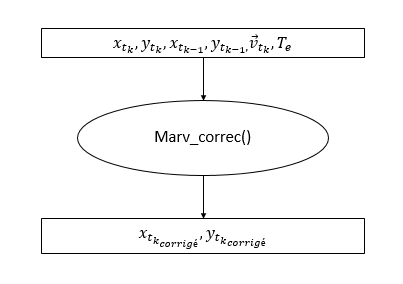

Exemple d'utilisation de la fonction marv_correc().m:

x_t_k = X_marv_num(301);
y_t_k = Y_marv_num(301);
x_t_k_minus = X_marv_num(300);
y_t_k_minus = Y_marv_num(300);
T_e_marv = 1/8; %%8Hz
v_x = 4; %arbitrary
v_y = -2;%arbitrary
marv_correc(x_t_k,y_t_k,x_t_k_minus,y_t_k_minus,T_e_marv,v_x,v_y);

## Deuxième étape de post-processing : calcul de la distance parcourue

L'objectif de cette fonction est de calculer 

## Troisième étape: Positionnement des tronçons